a=1+mod(964,3)

a = 2

Q1

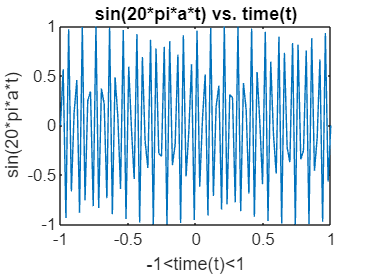

t=linspace(-1,1,100);
y1=sin(20*pi*a*t);
plot(t,y1);
title('sin(20*pi*a*t) vs. time(t)')
xlabel('-1<time(t)<1')
ylabel('sin(20*pi*a*t)')

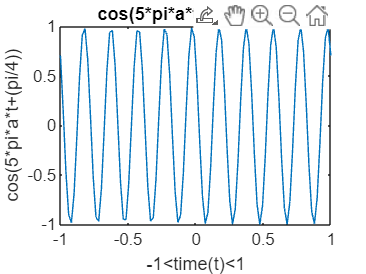


y2=cos(5*pi*a*t+(pi/4));
plot(t,y2)
title('cos(5*pi*a*t+(pi/4)) vs t')
xlabel('-1<time(t)<1')
ylabel('cos(5*pi*a*t+(pi/4))')

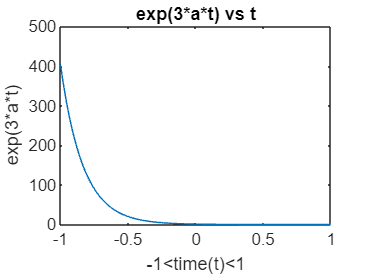


y3=exp(-3*a*t);
plot(t,y3)
title('exp(3*a*t) vs t')
xlabel('-1<time(t)<1')
ylabel('exp(3*a*t)')

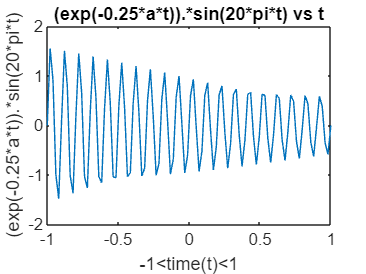


y4=(exp(-0.25*a*t)).*sin(20*pi*t);
plot(t,y4)
title('(exp(-0.25*a*t)).*sin(20*pi*t) vs t')
xlabel('-1<time(t)<1')
ylabel('(exp(-0.25*a*t)).*sin(20*pi*t)')

Q2

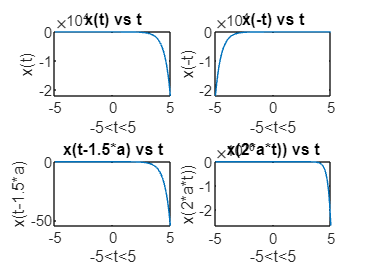

subplot(2,2,1)
t=linspace(-5,5,100);
x=inline('-exp((1+mod(964,3))*t)','t');
plot(t,x(t))
title('x(t) vs t')
xlabel('-5<t<5')
ylabel('x(t)')

subplot(2,2,2)
plot(t,x(-t))
title('x(-t) vs t')
xlabel('-5<t<5')
ylabel('x(-t)')

subplot(2,2,3)
plot(t,x(t-1.5*(1+mod(964,3))));
title('x(t-1.5*a) vs t')
xlabel('-5<t<5')
ylabel('x(t-1.5*a)')

subplot(2,2,4)
plot(t,x(2*(1+mod(964,3)*t)));
title('x(2*a*t)) vs t')
xlabel('-5<t<5')
ylabel('x(2*a*t))')

Q3(1)

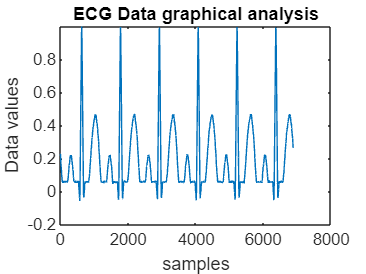

ecg=importdata("ECG_Data.txt");
load ECG_Data.txt
[n,p]=size(ECG_Data);
t=1:n;
figure;plot(t,ECG_Data)
title('ECG Data graphical analysis')
xlabel('samples')
ylabel('Data values')

Q3(2)

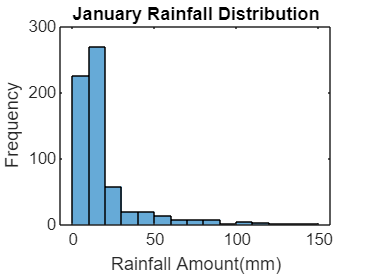

july=importdata("RainFallIndia_July.txt");
load RainFallIndia_July.txt
jan=load("RainFallIndia_Jan.txt");


histogram(jan(:,1))
title('January Rainfall Distribution')
ylabel('Frequency')
xlabel('Rainfall Amount(mm)')

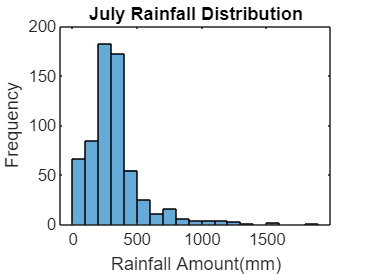


histogram(july(:,1))
title('July Rainfall Distribution')
ylabel('Frequency')
xlabel('Rainfall Amount(mm)')


MEAN_jan=mean(jan)

MEAN_jan = 18.3513

MEAN_july=mean(july)

MEAN_july = 326.0936

jan_SD=std(jan) %standard deviation for january month

jan_SD = 21.0991

july_SD=std(july) %standard deviation for july month

july_SD = 221.5326

Q3(3)

[s,fs]=audioread("Track002.wav");
sound(s,fs)

Q4

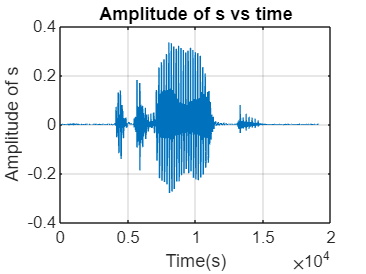

f=250*a;
[s,fs]=audioread("speech.wav");
%sound(s,fs)
y=s*cos(2*pi*f/fs);
%sound(y,fs)
figure;plot(s);

title('Amplitude of s vs time')
xlabel('Time(s)')
ylabel('Amplitude of s')

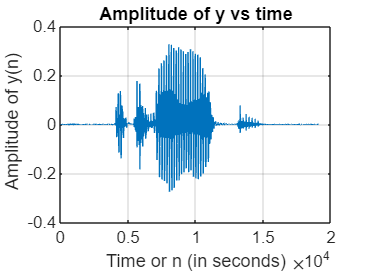

plot(y);

title('Amplitude of y vs time')
xlabel('Time or n (in seconds)')
ylabel(' Amplitude of y(n)')

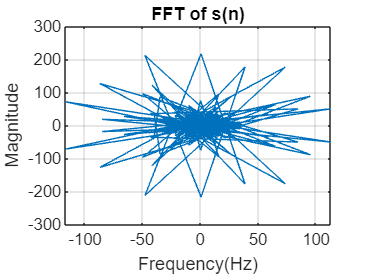

fourier_s=fft(s);

fourier_y=fft(y);
plot(fourier_s);

title('FFT of s(n)')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

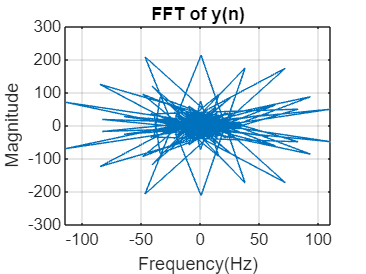

plot(fourier_y);

title('FFT of y(n)')
xlabel('Frequency(Hz)')
ylabel('Magnitude')

Q5

time_resolution = 0.001;
samples = 5000;
t = 0:time_resolution:(samples)* time_resolution

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



sin1 = sin(200 * a * t*2*pi);
sin1 = normalize(sin1,'range',[-1,1]);
% sound(sin1,1/time_resolution)
sin2 = sin(220 * a * t*2*pi);
sin2 = normalize(sin2,'range',[-1,1]);
 %sound(sin2,1/time_resolution)

combined_signal = sin1+sin2;
combined_signal = normalize(combined_signal,'range',[-1,1]);

filename = 'combined_sinusoids.wav';
audiowrite(filename, combined_signal, 1/time_resolution);
%sound(combined_signal, 1/time_resolution);



Q6

time_resolution = 0.001;
samples = 5000;
t = 0:0.1*time_resolution:(samples-1)* time_resolution

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


do=sin(2*pi*261.63*t);
re=sin(2*pi*293.66*t);
mi=sin(2*pi*329.63*t);
fa=sin(2*pi*349.23*t);
so=sin(2*pi*392*t);
la=sin(2*pi*440*t);
ti=sin(2*pi*493.88*t);

notes=[do re mi fa so la ti];
fs=44100;
filename='notes.wav';
audiowrite(filename,notes,fs);
%sound(notes,fs);

Q7

[s,fs]=audioread("Track002.wav");
% sound(s,fs)

y=load("ConvFile2.txt");
w=conv(s,y);
filename='w.wav';
audiowrite(filename,w,fs);
